Load in the Default project in order to get the data

addpath(fullfile(pwd,'mcmcstat'));
clear
defProj = load('defaultProject.mat');

defProj = defProj.problem;
refData = defProj.data{1};

Make the structure that contains xdata and ydata

data.xdata = refData(:,1);
data.ydata = refData(:,2);
setappdata(0,'refData',refData);

Make a plot of the data..

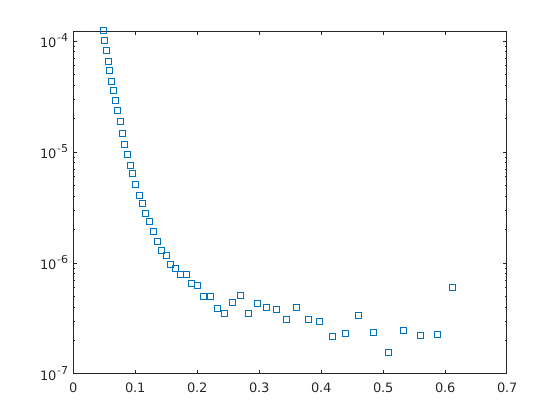

figure(1); clf
plot(data.xdata,data.ydata,'s');
set(gca,'YScale','log');

For MCMC, we need the sum of squares function. For the modelfun, we will use the parratt Reflectivity calculation. We've created a function 'modelfun.m' that does this calculation

modelfun = @(x,theta)calculationFun(x,theta)

modelfun = function_handle with value:
    @(x,theta)calculationFun(x,theta)


ssfun = @(theta,data) sum((data.ydata - modelfun(data.xdata,theta)).^2);

We know roughly the values in theta. But minimise with fminsearch to check everything

theta = [3; 0.08]

theta =     3.0000
    0.0800


[tmin,ssmin] = fminsearch(ssfun,theta,[],data)

tmin =     4.3461
    0.1006


ssmin = 6.1748e-12

Now estimate the error variance..

n = length(data.xdata);
p = 3;
mse = ssmin/(n-p) %Estimate for error variance

mse = 1.2350e-13

We then calculate the Jacobian as per the example

J = [data.xdata./(tmin(2)+data.xdata), ...
     -tmin(1).*data.xdata./(tmin(2)+data.xdata).^2];
tcov = inv(J'*J)*mse

tcov = 	1.0e+-13 *

    0.3295    0.0208
    0.0208    0.0016


Now define the inputs into the mcmcrun function. Start with the parameters cell array..

params = {
    {'Roughness', tmin(1), 0}
    {'Scalefactor', tmin(2), 0}
    };

Now we need to set up the 'model' structure. We need to set the sum of squares functin, and the initial estimate of the error variance.

model.ssfun = ssfun;
model.sigma2 = mse;
model.N = length(data.ydata);   %Total number of observations
model.S20 = model.sigma2;       %Prior mean for sigma2
model.N0 = 4;                   %Prior accuracy for sigma2


Now we need to se up the options struct...

options.nsimu = 7000;
options.updatesigma = 1;
options.qcov = tcov;
%options.burnintime = 3000;

Now run the simulation. Do three runs....

res = [];
[res,chain,s2chain,sschain] = mcmcrun(model, data, params, options, res);

Sampling these parameters:
name   start [min,max] N(mu,s^2)
Roughness: 4.34605 [0,Inf] N(0,Inf)
Scalefactor: 0.100571 [0,Inf] N(0,Inf)


[res,chain,s2chain,sschain] = mcmcrun(model, data, params, options, res);

Using values from the previous run
Sampling these parameters:
name   start [min,max] N(mu,s^2)
Roughness: 4.4995 [0,Inf] N(0,Inf)
Scalefactor: 0.101049 [0,Inf] N(0,Inf)


[res,chain,s2chain,sschain] = mcmcrun(model, data, params, options, res);

Using values from the previous run
Sampling these parameters:
name   start [min,max] N(mu,s^2)
Roughness: 4.57211 [0,Inf] N(0,Inf)
Scalefactor: 0.101184 [0,Inf] N(0,Inf)


We need to look at the outputs of the run. First examine the chain...

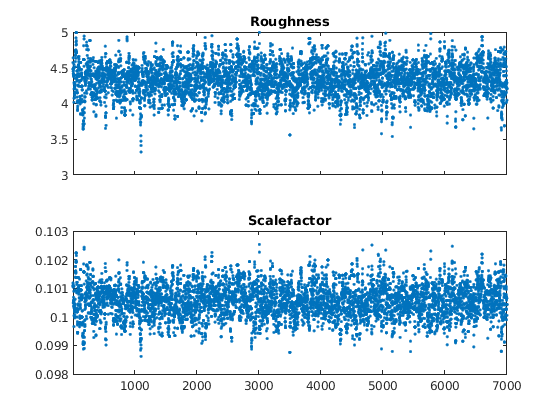

figure(2); clf
mcmcplot(chain,[],res,'chainpanel');

Look at parameter correlation....

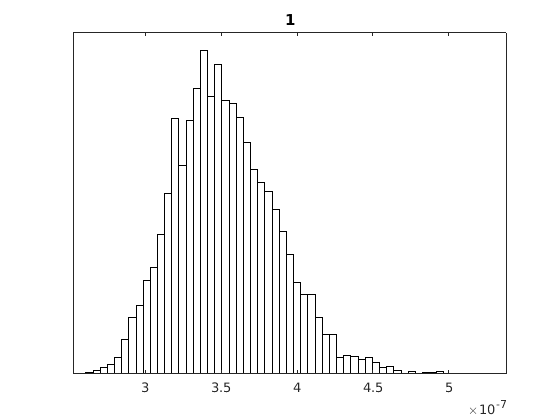

figure(3); clf
mcmcplot(chain,[],res,'pairs')
figure(4); clf
mcmcplot(sqrt(s2chain),[],[],'hist')

We can get the marginalised posteriors of the parameters by plotting the histograms of the chain....

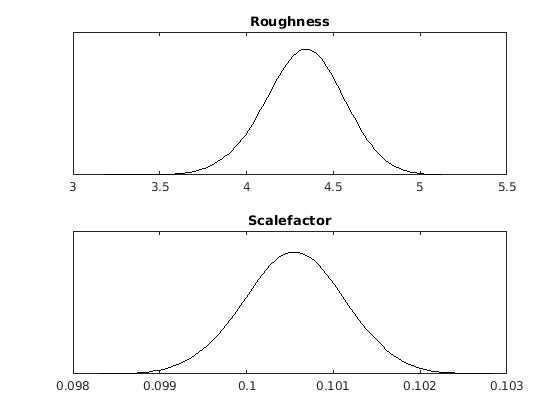

figure(5); clf
%mcmcplot(chain,[],{'Roughness','Scalefactor'},'hist
mcmcplot(chain,[],res,'denspanel', 2)

Now we need to run the direct comparison calculation. The 2D problem is small enough that we can calculate the likelihood on a grid, and then marginalise numerically in order to get the posteriors.

Following Sivia, the likelihod function for chi squared is given by exp(-chisq/2)

Start by making a grid to hold the calculated values...

%Use a 30 x 30 grid.
%Make an array for the results...
gridSize = 50;
probArray = zeros(gridSize);

%Make a vector of roughness values..
minRough = 2.5; 
maxRough = 8;
roughVector = linspace(minRough, maxRough, gridSize);

%Also scalefactor...
minScale = 0.08; 
maxScale = 0.12; 
scaleVector = linspace(minScale, maxScale, gridSize);


Now for the calculation.....

%Now for the calculation.
counter = 1;
totalGrid = gridSize^2;

for r = 1:gridSize
    for s = 1:gridSize
        thisScale =  scaleVector(s);
        thisRough = roughVector(r);
        theta(1) = thisRough;
        theta(2) = thisScale;
        ref = modelfun(data.xdata,theta);
        for i = 1:length(data.xdata)
            red_ss(i) = ((data.ydata(i) - ref(i))/refData(i,3))^2 ; 
        end
        chisq = (1/length(data.xdata)).*sum(red_ss);
        probArray(s,r) = exp(-chisq/2);
        percent = (counter/totalGrid)*100;
        fprintf('Calculated %1.1f percent \n',percent);
        counter = counter + 1;
    end
end

Calculated 0.0 percent 
Calculated 0.1 percent 
Calculated 0.1 percent 
Calculated 0.2 percent 
Calculated 0.2 percent 
Calculated 0.2 percent 
Calculated 0.3 percent 
Calculated 0.3 percent 
Calculated 0.4 percent 
Calculated 0.4 percent 
Calculated 0.4 percent 
Calculated 0.5 percent 
Calculated 0.5 percent 
Calculated 0.6 percent 
Calculated 0.6 percent 
Calculated 0.6 percent 
Calculated 0.7 percent 
Calculated 0.7 percent 
Calculated 0.8 percent 
Calculated 0.8 percent 
Calculated 0.8 percent 
Calculated 0.9 percent 
Calculated 0.9 percent 
Calculated 1.0 percent 
Calculated 1.0 percent 
Calculated 1.0 percent 
Calculated 1.1 percent 
Calculated 1.1 percent 
Calculated 1.2 percent 
Calculated 1.2 percent 
Calculated 1.2 percent 
Calculated 1.3 percent 
Calculated 1.3 percent 
Calculated 1.4 percent 
Calculated 1.4 percent 
Calculated 1.4 percent 
Calculated 1.5 percent 
Calculated 1.5 percent 
Calculated 1.6 percent 
Calculated 1.6 percent 
Calculated 1.6 percent 
Calculated 1.7 p

Plot the array....

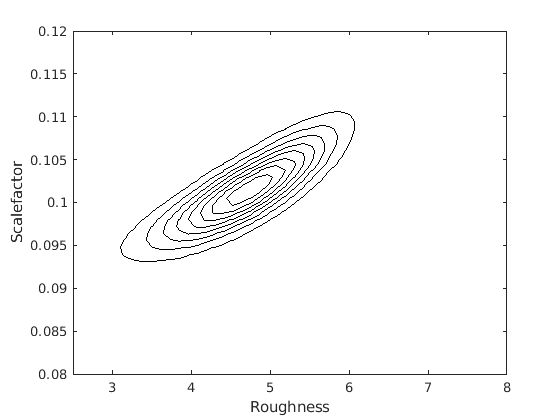

figure(6); clf
contour(roughVector,scaleVector,probArray,'k-');
ylabel('Scalefactor'); xlabel('Roughness')

To get the posteriors, we just integrate over the other dimension..

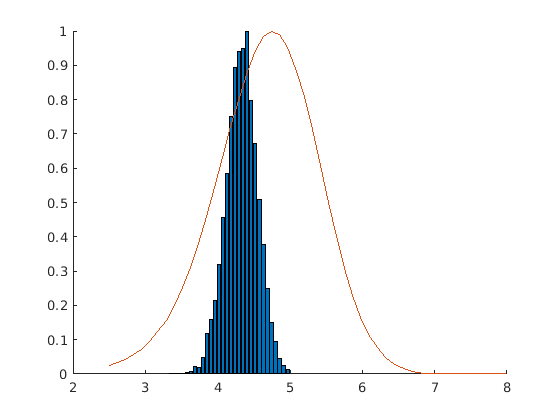

post_Roughness = trapz(probArray,1);
post_Scalefactor = trapz(probArray,2);

post_Roughness = [roughVector(:) post_Roughness(:)];
post_Scalefactor = [scaleVector(:) post_Scalefactor(:)];

figure(7); clf;
subplot(2,1,1); clf; hold on
r = chain(:,1);
[r_n,r_bin] = hist(r,30);
r_n = r_n ./ max(r_n);
bar(r_bin,r_n);

hold on
post_Roughness(:,2) = post_Roughness(:,2) ./ max(post_Roughness(:,2));
plot(post_Roughness(:,1), post_Roughness(:,2))